# Lab 6 - Confidence Intervals

Thomas Conaway

Lab Partners: Jeff Jiang, Avi Soval

We will be exploring injections of simulated signals into signal free background data.

Generating a fake LHC background with mean 100:

clc; clear; close all;
lhcbg = makedist("Poisson","lambda",100);

## Problem 1

Determining the 5 sigma sensitivity threshold for our fake LHC background.

fivesigma = icdf(lhcbg,1 - 3.5E-6)

fivesigma = 148

## Problem 2

We will inject a set of moderately strong single strength signals into the background. To be moderately strong we will pick a signal strength within the range 8 to 30 sigma.

abs(norminv(cdf(lhcbg,300,'upper')))

ans = 16.1463

A signal strength of 300 is within this range, so we will use this as the strength and proceed:

size = 10000;
poissnoise = poissrnd(100,[1,size]);
signal300 = zeros(1,size);
signal300(randi(numel(signal300),[1,500])) = 300; % sets 500 random elements to 300
obssignal = poissnoise + signal300;

**a)** Histogramming how "bright" the observed signal appears to be: *check what brightness means

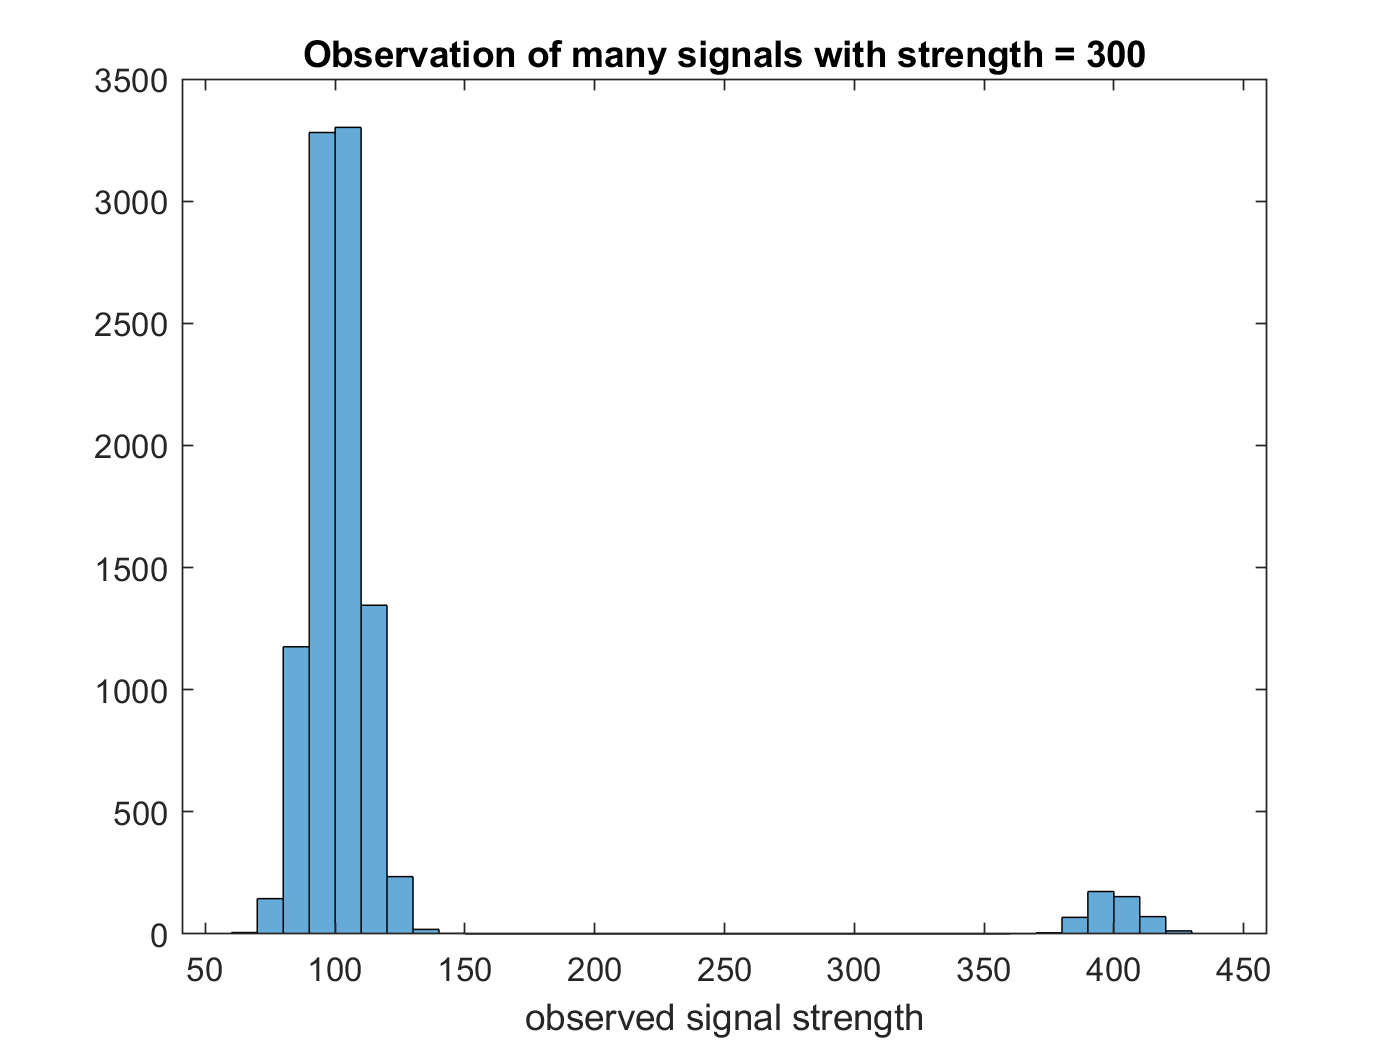

histogram(obssignal);
title("Observation of many signals with strength = 300");
xlabel("observed signal strength");

Signal appears as the group of bins centered at 400. Shape appears to be the same as the background noise. This histogram is telling us that the observed signal can take on a range of values that it picks up from the background.

**b)** Observed signal appears biased per the official proclamation. It is not centered on the true injected signal; it is always stronger. The shape of the observed signal is symmetric. *is symmetric here used for the shape or something else?

## Problem 3

Suite of injected signals (like in lecture 14):

signals = 0:1:550; % 550 gets a little over 31 sigma

a) We will now be simulating observed signals for a range of injected signals, plotted as a 2d histogram.

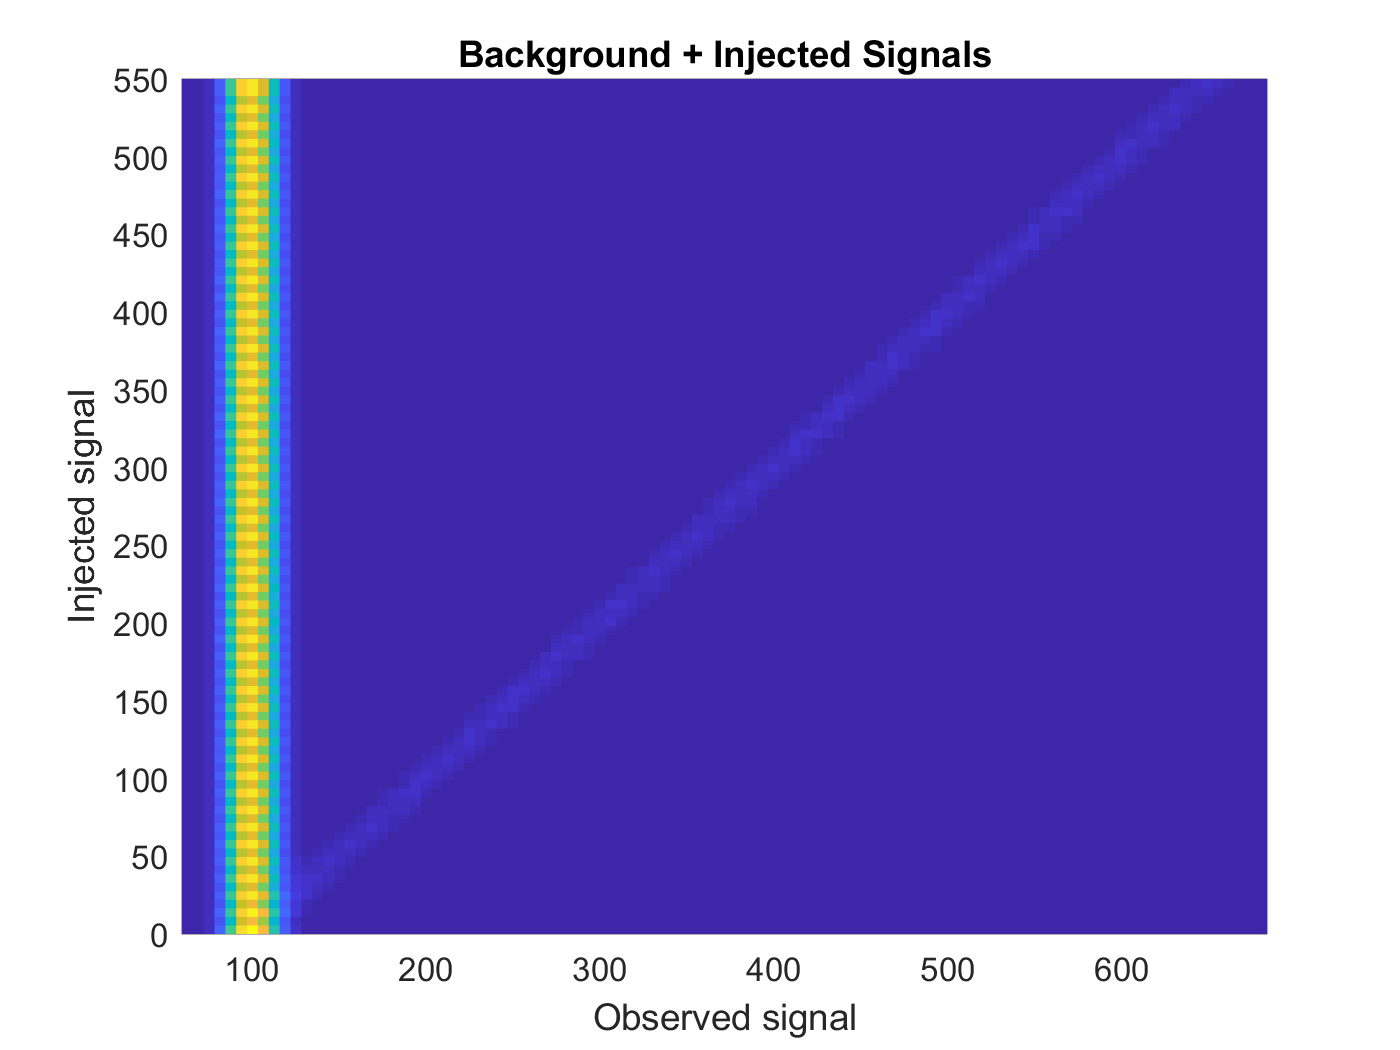

size = 10000;
poissnoise = poissrnd(100,[1,size]); % may want to redo for each row?
poisssignalsyval = zeros(numel(signals),size);
obssignals = zeros(numel(signals),size);
justsignals = zeros(numel(signals),size);
for k = 1:numel(signals) % loop to build and stack each row slice
    poisssignalsyval(k,:) = signals(k);
    signalk = zeros(1,size);
    indices = randi(numel(signalk),[1,500]);
    signalk(indices) = signals(k);    
    obssignals(k,:) = poissnoise + signalk;
    justsignals(k,indices) = obssignals(k,indices);
end
justsignals(justsignals == 0) = nan; % so it can play nice with histogram2

histogram2(obssignals,poisssignalsyval,100,'DisplayStyle','tile','ShowEmptyBins','on');
title("Background + Injected Signals");
ylabel("Injected signal");
xlabel("Observed signal");

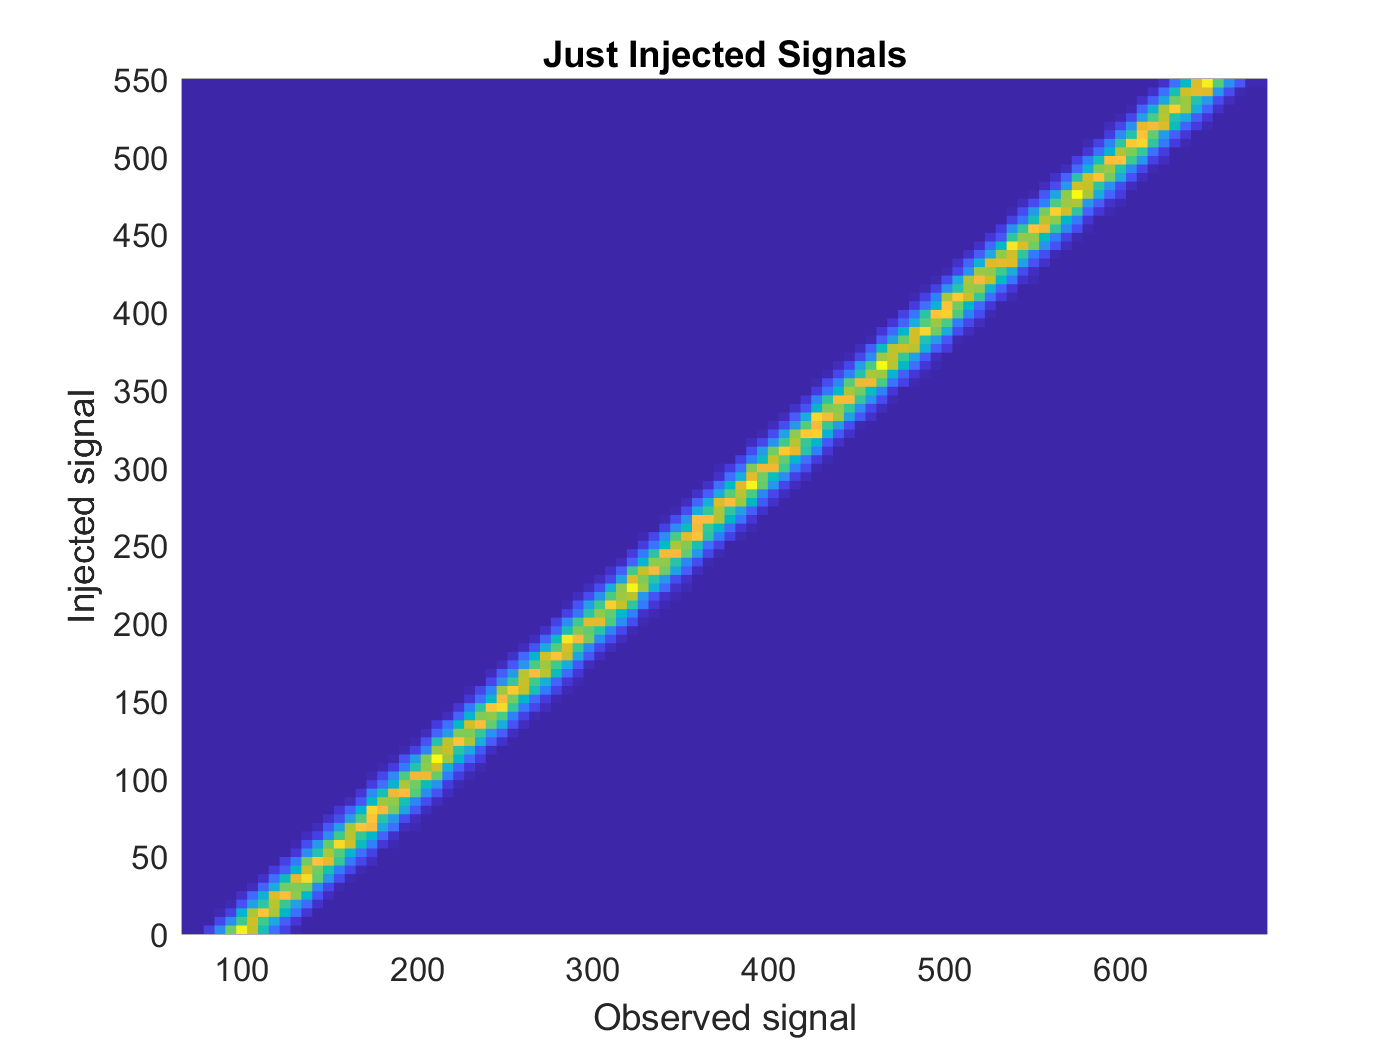

histogram2(justsignals,poisssignalsyval,100,'DisplayStyle','tile','ShowEmptyBins','on');
title("Just Injected Signals");
ylabel("Injected signal");
xlabel("Observed signal");

**b)** Checking if I get the same answer as in Problem 2 for the same injected signal:

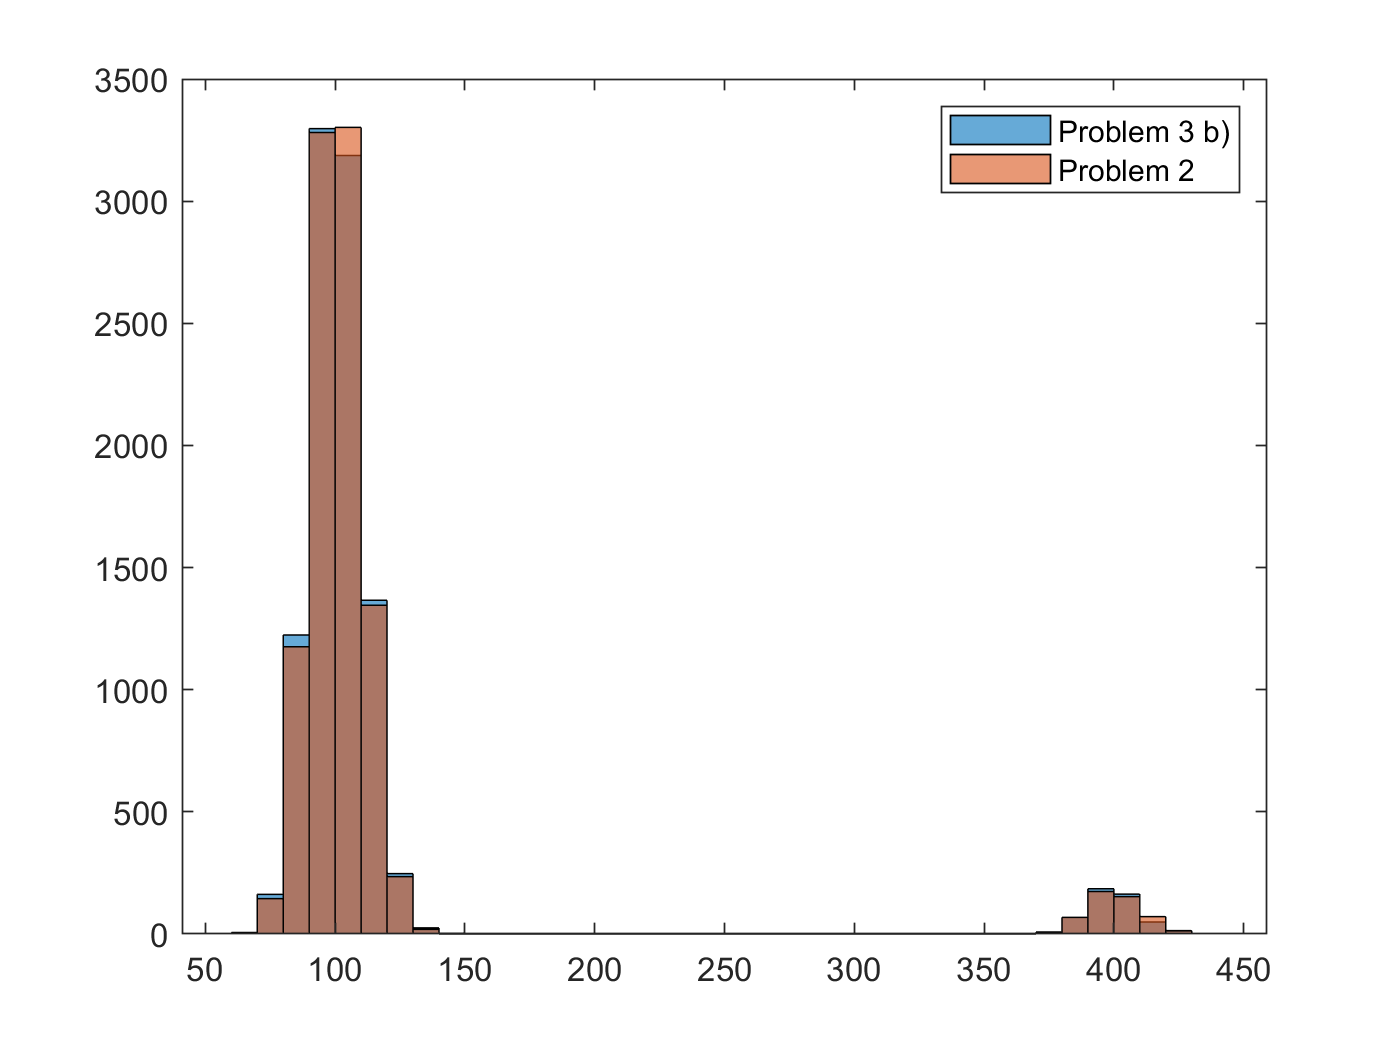

histogram(obssignals(300,:));
hold on;
histogram(obssignal);
legend("Problem 3 b)","Problem 2");
hold off;

Looks good. The method I used for generating the suite produced a different random set of noise, but they still closely follow the original histogram for an injected signal of 300. 

**c)** Observed signal 300 vertical histogram:

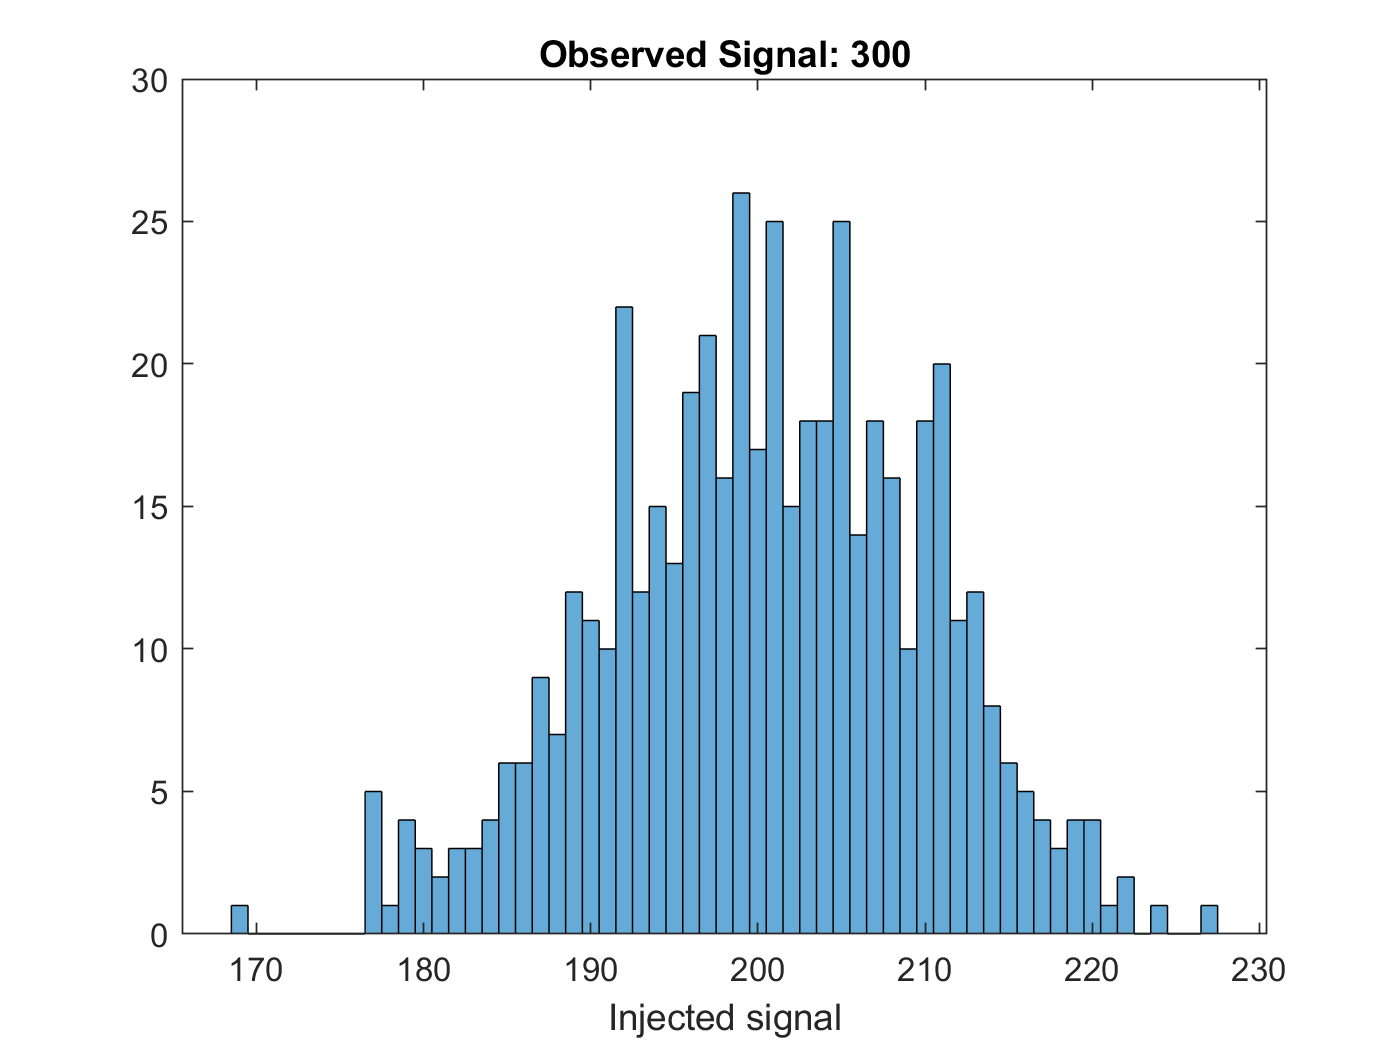

injected = poisssignalsyval(abs(justsignals - 300)<0.05);
binedges = min(injected)-0.5:max(injected)+0.5;
histogram(injected,binedges);
title("Observed Signal: 300");
xlabel("Injected signal");

This histogram gives the range and probabilities of the injected signals that can produce an observed signal of 300. *should I make this into a pdf()?

**d)** For an observed signal of 300, the one sigma uncertainty on the true signal strength are the bounds around the true signal that contain 68% of the data.

% not sure what the "true signal" is in this case. do we have to calculate
% something for each injected signal? or the 300 injected signal?
% uncertainty bounds should be on the "true signal strength". what is the
% true signal strength for an observed signal of 300? 200?

% just gonna find 1 sigma for this distribution slice and calculate
% uncertainty values.
[p, edges] = histcounts(injected,binedges,'Normalization','pdf');
sumup = 0;
lowerunc = 0;
meanval = 0;
upperunc = 0;
% this is still messy, try to find a better way or clean up
for k = 1:numel(p)
    sumup = sumup + p(k);
    if sumup > 0.84 && upperunc == 0
        upperunc = edges(k) + 0.5;
        break
    end
    if sumup > .50 && meanval == 0
        meanval = edges(k) + 0.5;
    end
    if sumup > 0.16 && lowerunc == 0
        lowerunc = edges(k) + 0.5;
    end
end
disp(meanval + " (+" + (meanval-lowerunc) + "|-" + (upperunc-meanval) + ")"); % this still doesn't feel right

201 (+10|-10)


**e)** Not perfectly symmetric because different uncertainty bounds, though this may be due to random noise depending on what values are rolled. I would say it is roughly symmetric. It is definitely biased because the observed signal does not match the injected one by 100. *not quite ready to say this makes sense*

## Problem 4

We will now look at what happens when we have a weak signal (within 1 sigma of the background).

**a)** We will look at an observed signal of 105 and calculate the injected signal pdf() histogram as we did above.

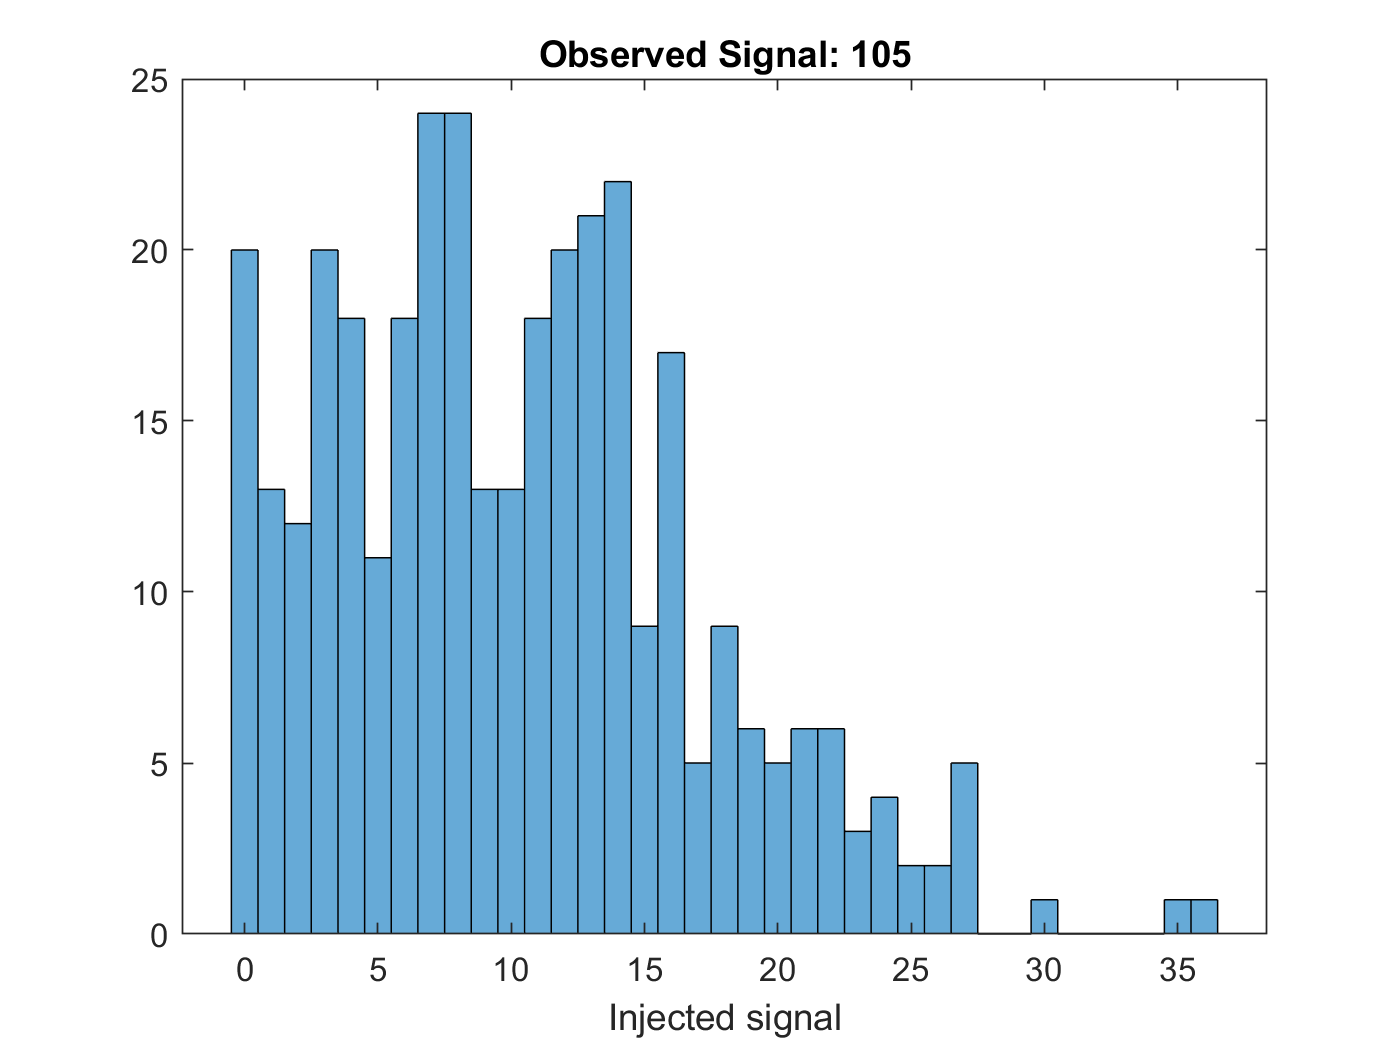

weaksignal = 105;
injected3 = poisssignalsyval(abs(justsignals - weaksignal)<0.05);
binedges3 = min(injected3)-0.5:max(injected3)+0.5;
histogram(injected3,binedges3);
title("Observed Signal: " + weaksignal);
xlabel("Injected signal");

Resulting pdf() extends to zero.

**b)** If the true signal pdf() extends to zero then it becomes probable for the background (no signal) to produce the observation.

**c)** Even if the observed signal is too weak to claim a detection, we can determine an upper confidence bound value which the true signal would have to be less than 95% of the time.

% if I'm reading this right, this is asking for the signal strength which is
% to the right of 95% of all the potential signals for that observation.
% again, it may be worth finding the pdf() instead of doing it by hand.

binedges3 = min(injected3)-0.5:max(injected3)+0.5;
p3 = histcounts(injected3,binedges3,'Normalization','pdf');
sumup3 = 0;
for k = 1:numel(p3)
    sumup3 = sumup3 + p3(k);
    if sumup3 > 0.95
        break;
    end
end
upperconf = binedges3(k) + 0.5

upperconf = 23